# Saving files (regular and gif)

clear;clc;

## Create figures

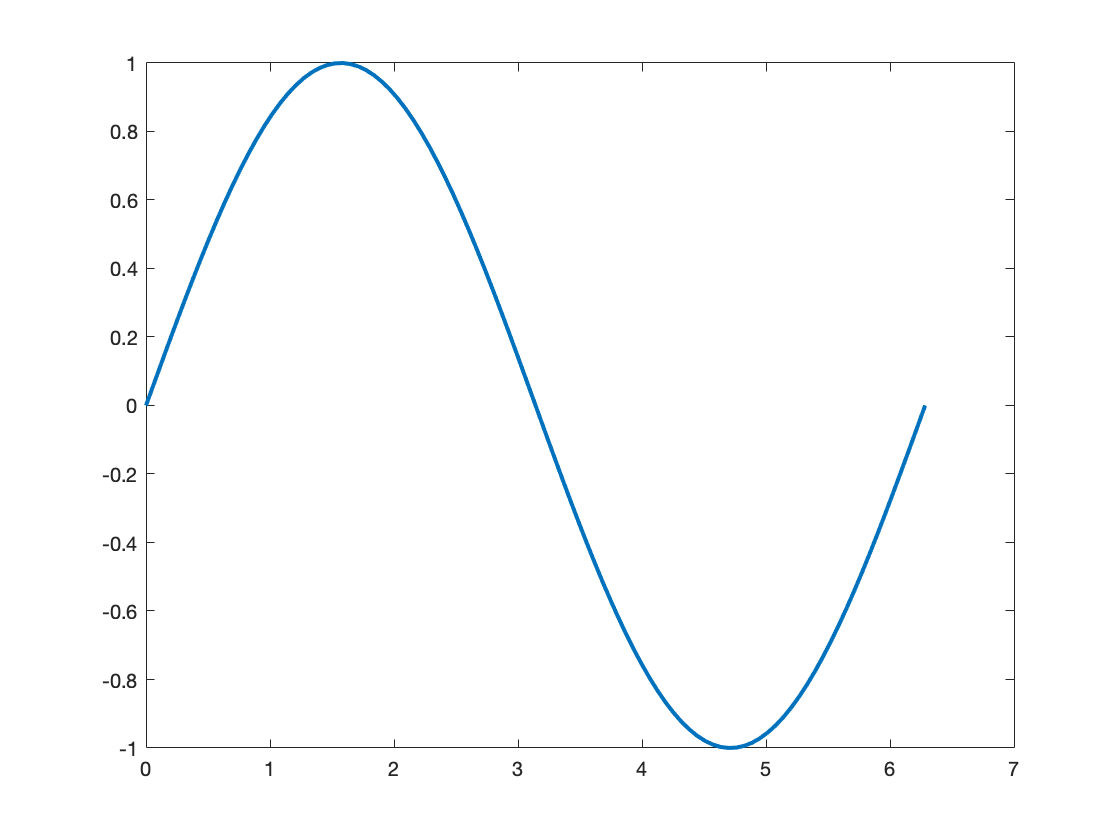

x = linspace(0, 2*pi, 100); % to evaluate

% visualize
figure()
plot(x, sin(x), 'linewidth', 2);
best_save('testFig1')

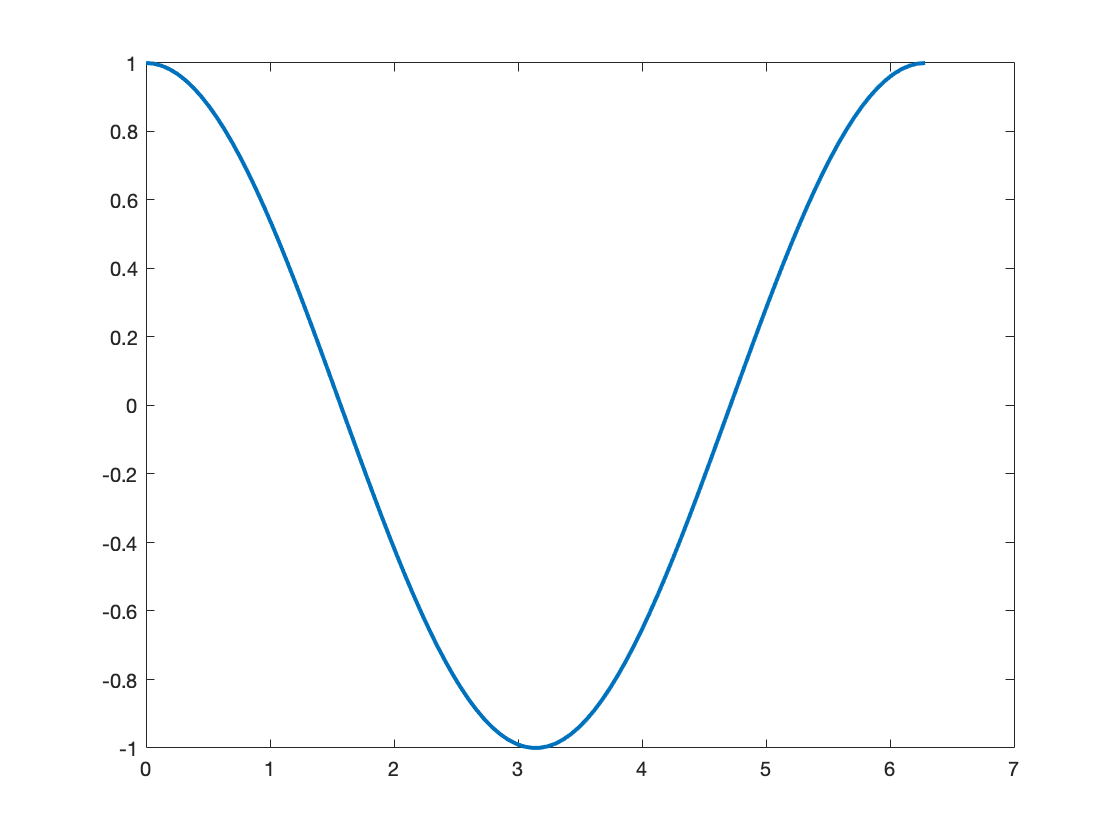

% visualize
figure()
plot(x, cos(x), 'linewidth', 2);
best_save('testFig2', 'sup',true)

## Create gifs

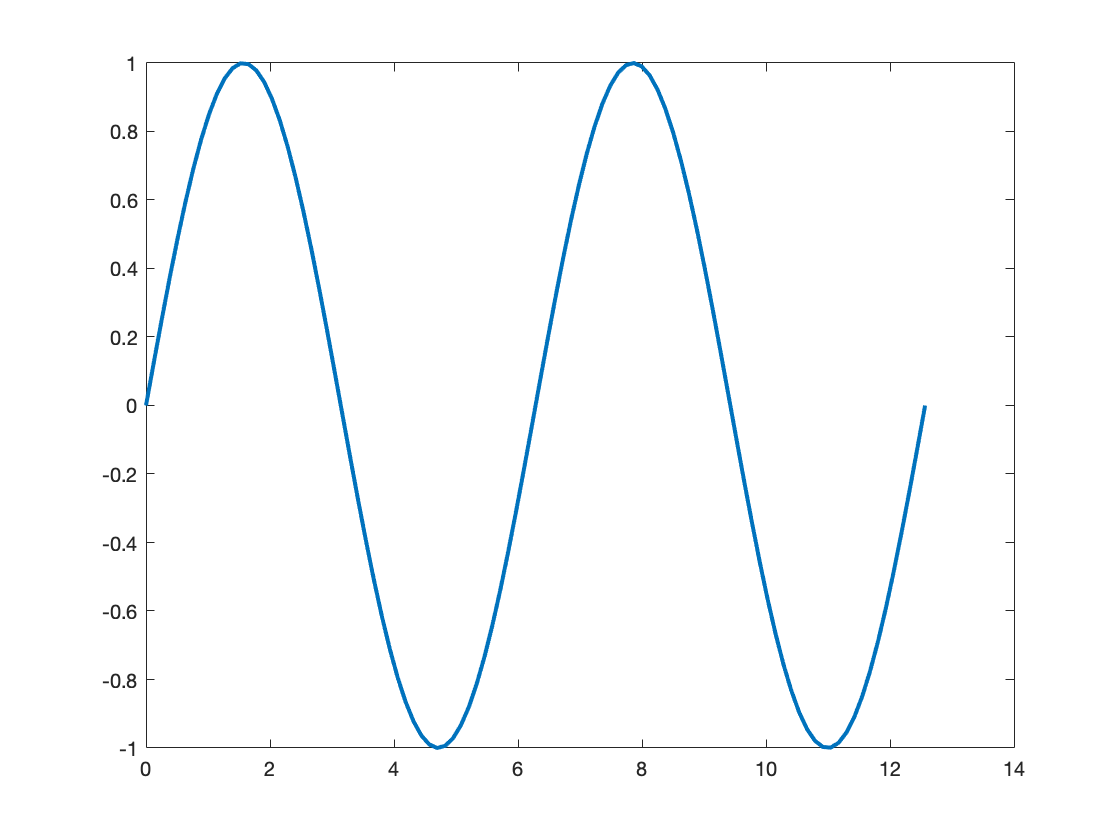

x_end = linspace(2*pi, 4*pi, 100); % make look bigger 

% sin 
% initialize
figure()
plot(x, sin(x), 'linewidth', 2);
ax = gca(); 

for i = 1:length(x_end)
    set(ax.Children(1), 'xdata', linspace(0, x_end(i)));
    set(ax.Children(1), 'ydata', sin(linspace(0, x_end(i))));
    writeGif('testGif1.gif', i)
end


% cos
% initialize
figure()
plot(x, sin(x), 'linewidth', 2);
ax = gca(); 

for i = 1:length(x_end)
    set(ax.Children(1), 'xdata', linspace(0, x_end(i)));
    set(ax.Children(1), 'ydata', sin(linspace(0, x_end(i))));
    writeGif('testGif2.gif', i, 'delayTime',0.5)
end